Solução numérica e analítica da equação a diferenças (2.22 (C)) - Resposta completa

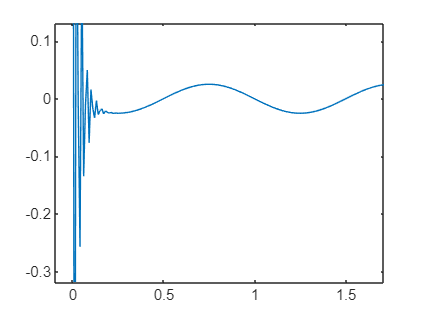

% Solução Numérica
n = 0:0.01:10;
Coef = [1 1 1/2];
mat_ind = [1 -1];
y0 = filtic(mat_ind, Coef, [0 0]);
x = cos(2*pi*n);
y = filter(mat_ind, Coef, x, y0);
plot(n,y)

% Solução analítica
n = 0:10;
ya = ((-1+1i)/2).^n + 11.4j*((-1-1i)/2).^n + 6/5*cos(2*pi*n);

stem(n,ya,'--red')